clear
M = 32e-3   % Molar mass of oxygen

M =         0.032

R = 8.31

R =          8.31

v = linspace(0,1200)';
T = [300 80]

T =    300    80


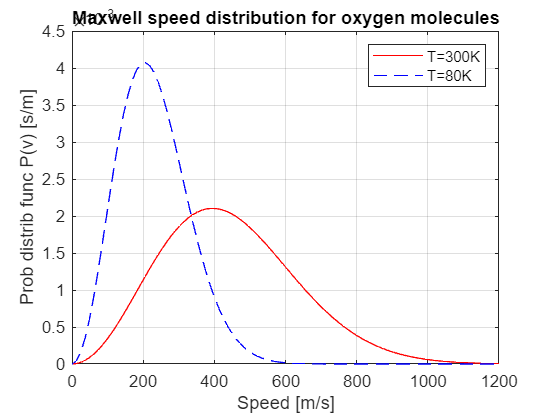

P = 4*pi*(M./(2*pi*R*T)).^(3/2).*v.^2.*exp(-M*v.^2./(2*R*T));
plot(v,P(:,1),'r-',v,P(:,2),'b--'), grid on
title('Maxwell speed distribution for oxygen molecules')
xlabel('Speed [m/s]'), ylabel('Prob distrib func P(v) [s/m]')
legend('T=300K','T=80K')

Average speed, root mean square speed and most probable speed

syms v T R M real positive
P = 4*pi*(M/(2*pi*R*T))^(3/2)*v^2*exp(-M*v^2/(2*R*T))

$$P = 4\,\pi \,v^{2}\,{\mathrm{e}}^{-\frac{M\,v^{2}}{2\,R\,T}}\,{\left(\frac{M}{2\,R\,T\,\pi }\right)}^{3/2}$$

vavg = int(v*P,0,Inf)       % v average

$$vavg = \frac{2\,\sqrt{2}\,\sqrt{R}\,\sqrt{T}}{\sqrt{M}\,\sqrt{\pi }}$$

vsqavg = int(v^2*P,0,Inf);
vrms = sqrt(vsqavg)         % v rms

$$vrms = \frac{\sqrt{3}\,\sqrt{R}\,\sqrt{T}}{\sqrt{M}}$$

vp = solve(diff(P,v)==0,v)  % most probable speed

$$vp = \frac{\sqrt{2}\,\sqrt{R}\,\sqrt{T}}{\sqrt{M}}$$